Folder = cd;
Folder = fullfile(Folder, '..');

%Load OpenCV stitch image
% stitch_load = load('../scans/scan1/traverse0/stitch.mat');
% stitch = stitch_load.X;
% stitch = imrotate(stitch,90);
%Load MIST stitch image
% mist = imread('../scans/scan1/traverse0/MIST/mist.tif')
mist = imrotate(mist,90);

%Swapping RGB value to get real color (RGB value change while converting
%from numpy (.npy) to matlab (.mat))
clear truecolors_stitch

truecolors_stitch(:,:,1)=stitch(:,:,3);
truecolors_stitch(:,:,2)=stitch(:,:,2);
truecolors_stitch(:,:,3)=stitch(:,:,1);

% truecolors_cropped_stich(:,:,1)=cropped_stich(:,:,3);
% truecolors_cropped_stich(:,:,2)=cropped_stich(:,:,2);
% truecolors_cropped_stich(:,:,3)=cropped_stich(:,:,1);


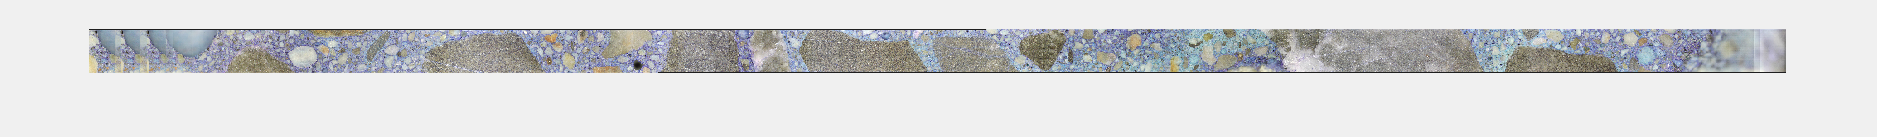

%Show stitch
figure(1);
set(gcf,'Visible','on')
imshow(mist)

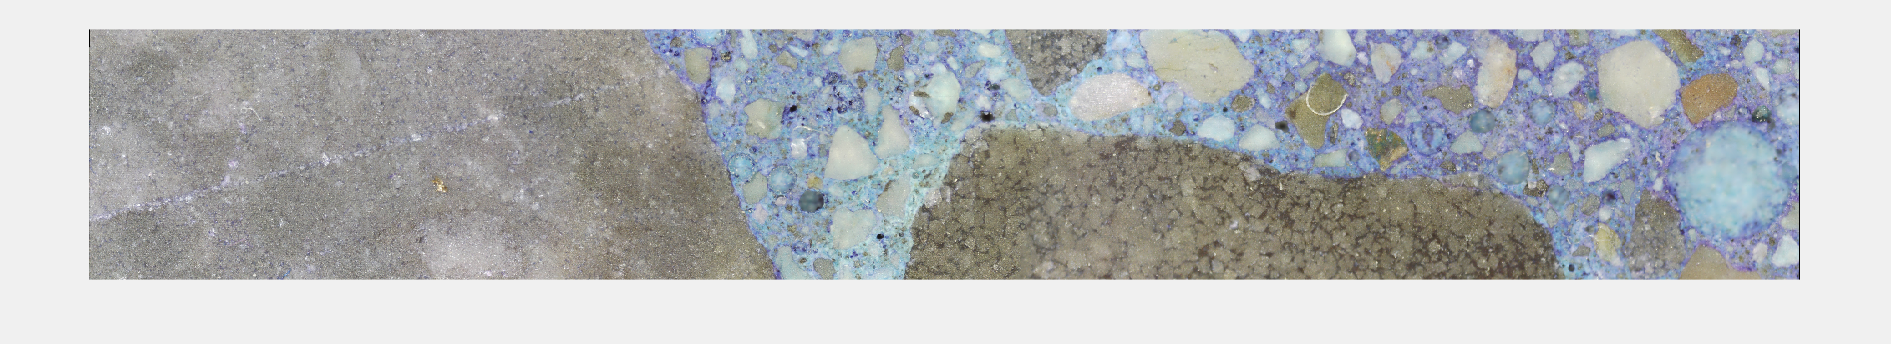


figure(2);
set(gcf,'Visible','on')
imshow(truecolors_stitch)

imwrite(truecolors_stitch,'tests/test2/scan0/rotated_stitch.tif')